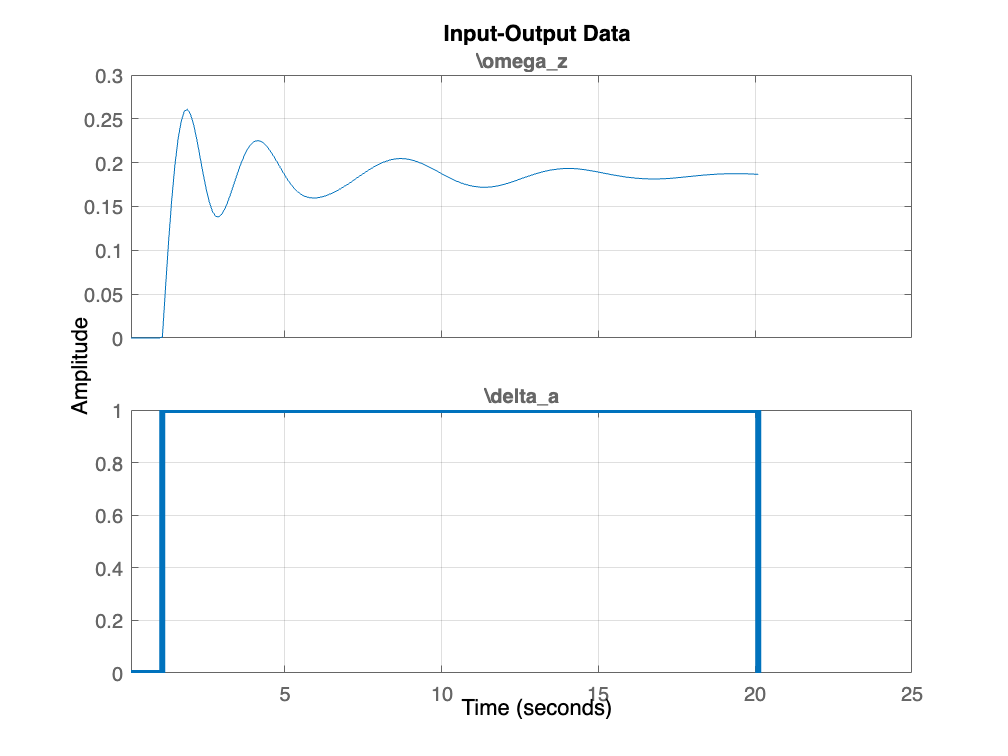

clear all; close all; clc

load simdata/step_20s_simdata.mat
% gives times, delta_a and omega_z arrays
Ts = times(2) - times(1);

% use iddata to collect and plot input/output data
data = iddata(omega_z, delta_a, Ts);
data.InputName  = '\delta_a';
data.InputUnit = '[fraction]';
data.OutputName = '\omega_z';
data.OutputUnit = 'rad/s';
data.TimeUnit = 'seconds';
plot(data);
set(findall(gca, 'Type', 'Line'), 'LineWidth', 3);
grid on

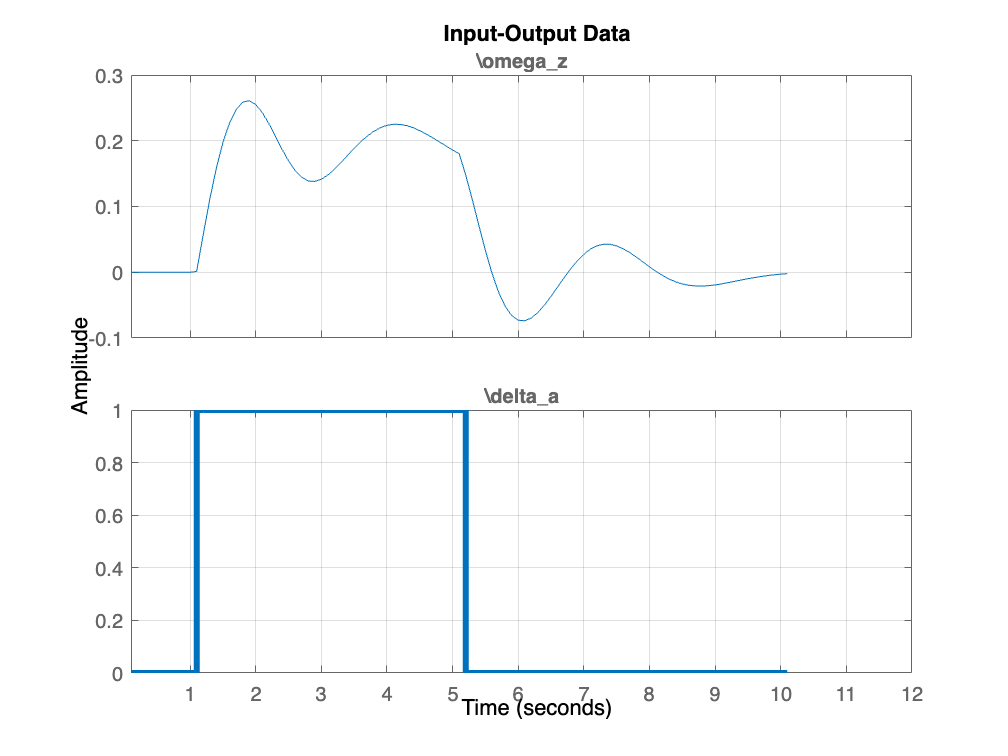

% collect and plot validation data
clear delta_a omega_z times
load simdata/shortstep_simdata.mat
% delta_a, omega_z, and times gets overwritten
Ts = times(2) - times(1);

validation_data = iddata(omega_z, delta_a, Ts);
validation_data.InputName  = '\delta_a';
validation_data.InputUnit = '[fraction]';
validation_data.OutputName = '\omega_z';
validation_data.OutputUnit = 'rad/s';
validation_data.TimeUnit = 'seconds';
plot(validation_data);
set(findall(gca, 'Type', 'Line'), 'LineWidth', 3);
grid on

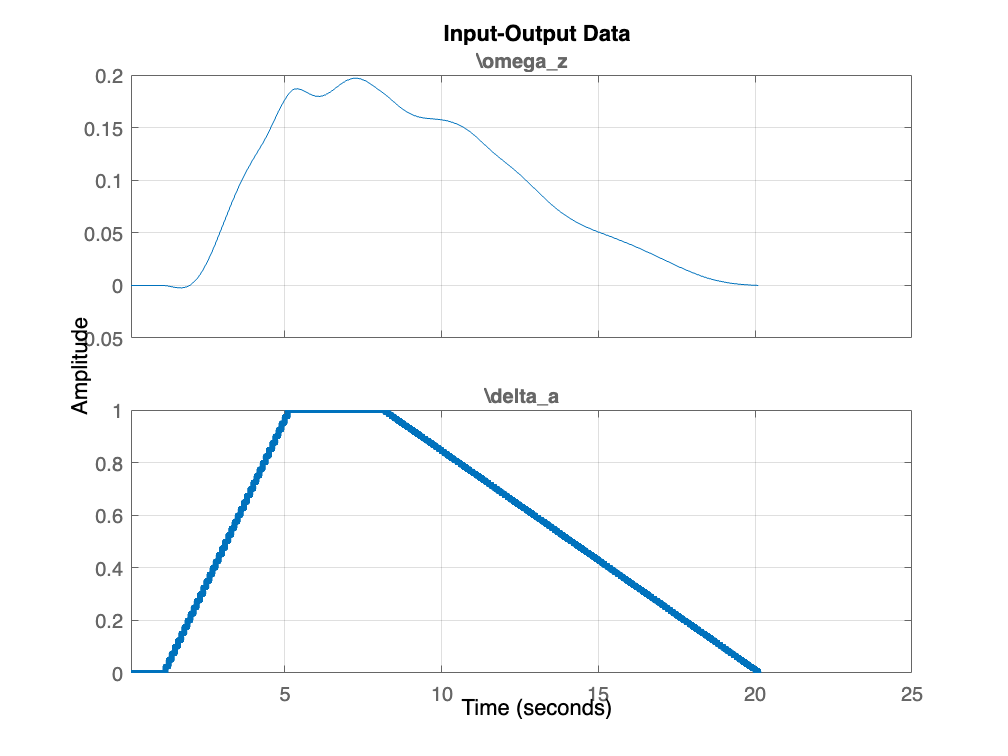



% collect and plot another set of validation data
clear delta_a omega_z times
load simdata/ramp_simdata.mat
% delta_a, omega_z, and times gets overwritten
Ts = times(2) - times(1);

validation_data2 = iddata(omega_z, delta_a, Ts);
validation_data2.InputName  = '\delta_a';
validation_data2.InputUnit = '[fraction]';
validation_data2.OutputName = '\omega_z';
validation_data2.OutputUnit = 'rad/s';
validation_data2.TimeUnit = 'seconds';
plot(validation_data2);
set(findall(gca, 'Type', 'Line'), 'LineWidth', 3);
grid on


% fit first-order TF
sysTF = tfest(data, 2,1) % TF: 2 poles, 1 zero

sysTF =
  From input "\delta_a" to output "\omega_z":
    0.4339 s + 1.933
  --------------------
  s^2 + 1.87 s + 10.46
 
Continuous-time identified transfer function.

Parameterization:
   Number of poles: 2   Number of zeros: 1
   Number of free coefficients: 4
   Use "tfdata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                          
Estimated using TFEST on time domain data "data".
Fit to estimation data: 75.15%                   
FPE: 0.0001464, MSE: 0.0001379                   
 
Model Properties


**Validate Model**

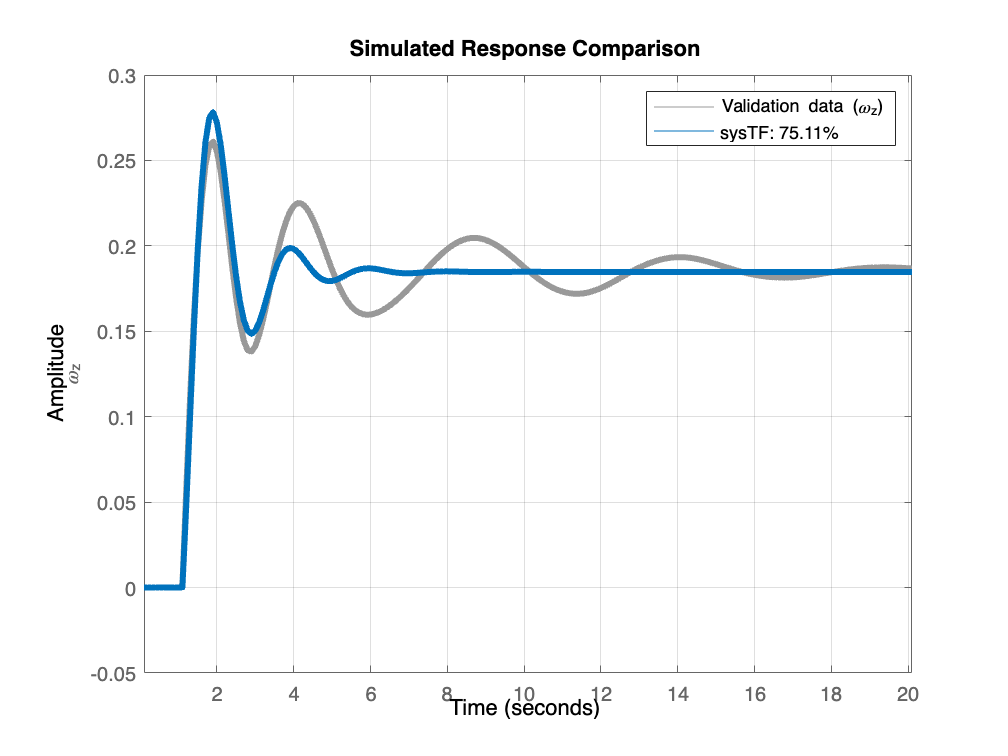

opt = compareOptions;
opt.InitialCondition = 'z';
compare(data, sysTF, opt)
set(findall(gca, 'Type', 'Line'), 'LineWidth', 3);
grid on

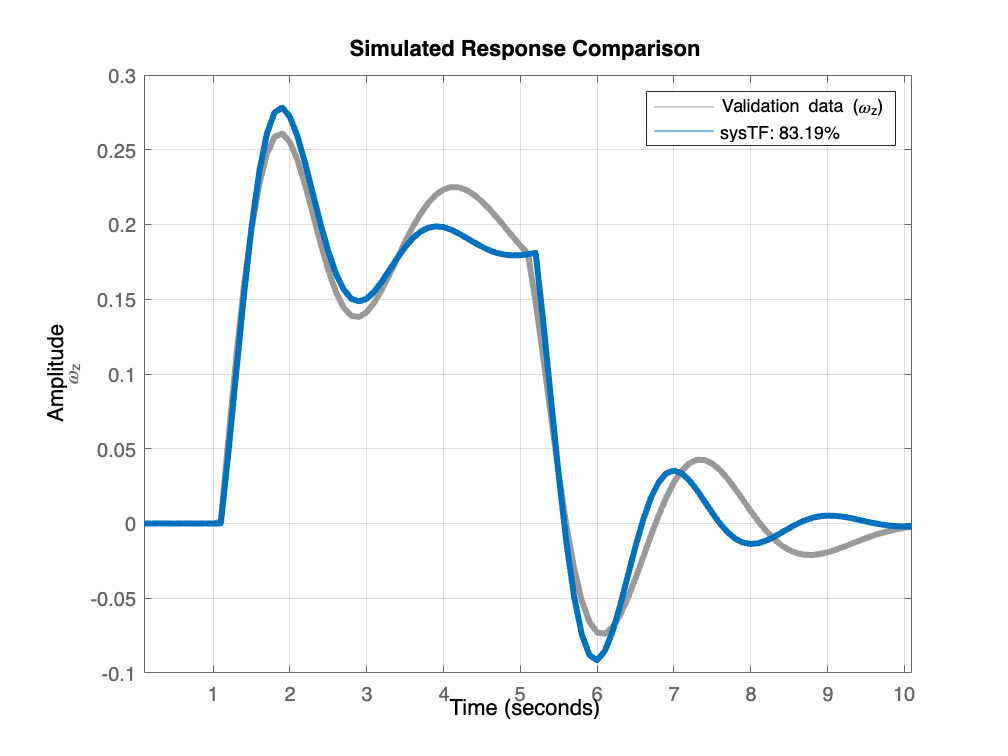

compare(validation_data, sysTF, opt)
set(findall(gca, 'Type', 'Line'), 'LineWidth', 3);
grid on

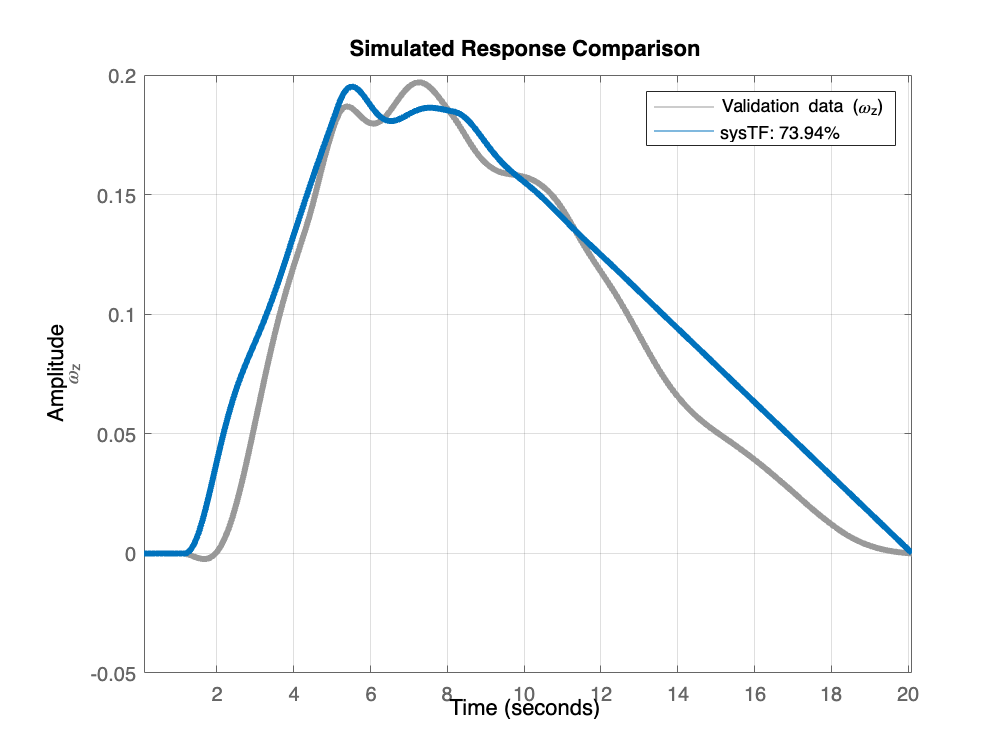

compare(validation_data2, sysTF, opt)
set(findall(gca, 'Type', 'Line'), 'LineWidth', 3);
grid on

**Identify a state space model**

Gss = ssest(data, 1:10) % estimate state space model of order 1:10

Gss =
  Continuous-time identified state-space model:
      dx/dt = A x(t) + B u(t) + K e(t)
       y(t) = C x(t) + D u(t) + e(t)
 
  A = 
             x1        x2        x3        x4
   x1   -0.1273     1.338    0.1761  -0.00692
   x2    -1.041   -0.1169    0.3283    0.1646
   x3   -0.2831   -0.5568    -1.121    -2.106
   x4   -0.4072    -1.846     2.792    -2.056
 
  B = 
       \delta_a
   x1    -4.005
   x2    -5.477
   x3     86.81
   x4     99.25
 
  C = 
                    x1         x2         x3         x4
   \omega_z    -0.1104   -0.03507  -0.009073   0.006984
 
  D = 
             \delta_a
   \omega_z         0
 
  K = 
       \omega_z
   x1    -43.11
   x2    -126.2
   x3    -352.5
   x4    -654.7
 
Parameterization:
   FREE form (all coefficients in A, B, C free).
   Feedthrough: none
   Disturbance component: estimate
   Number of free coefficients: 28
   Use "idssdata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                

Gest = tf(Gss) % turn stat-space back into TF

Gest =
 
  From input "\delta_a" to output "\omega_z":
  0.5396 s^3 + 2.336 s^2 + 0.8129 s + 2.141
  ------------------------------------------
  s^4 + 3.421 s^3 + 10.9 s^2 + 6.3 s + 12.16
 
Continuous-time transfer function.
Model Properties


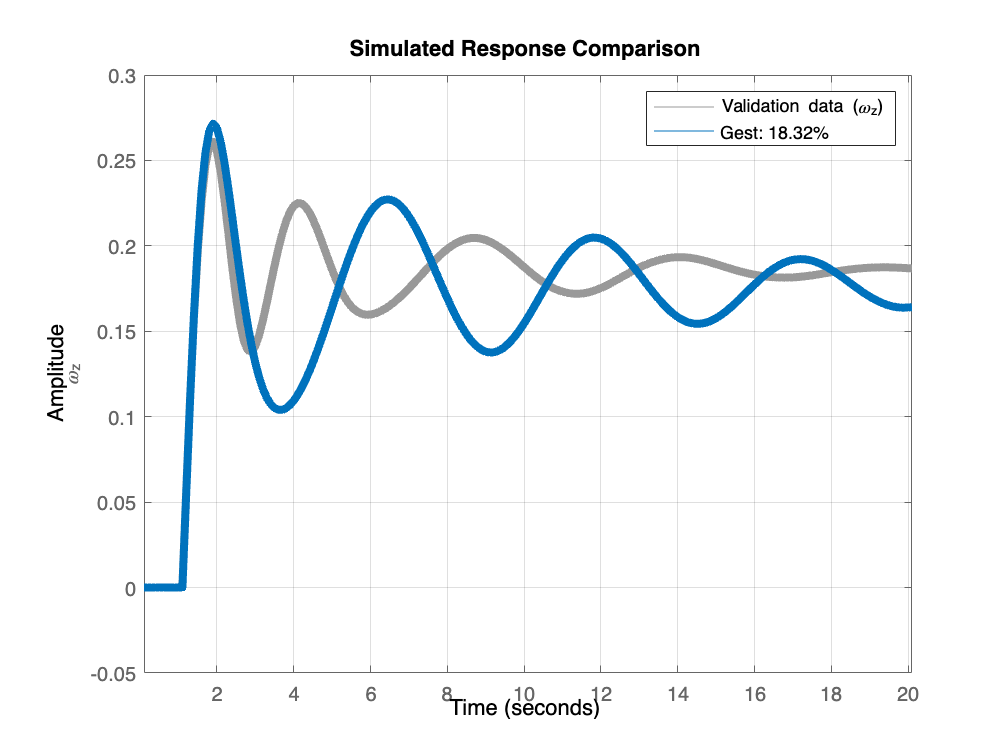

opt = compareOptions;
opt.InitialCondition = 'z';
compare(data, Gest, opt)
set(findall(gca, 'Type', 'Line'), 'LineWidth', 4);
grid on